# Numerical Solution of ODEs

Solving a differential equation requires us to evaluate an integral, and as we know, not all integrals can be evaluated analytically. This means that we often have to resort to numerical methods to find our solutions. There are many methods for solving ordinary differential equations, and here we will look at some of the simplest. 

Programming systems such as Matlab and Python have very good built-in commands to solve ordinary differential equations of many different types. However, to start with, we will program our own algorithms because doing so helps us to learn about the possible pitfalls and behaviors of these methods. 

# The Forward Euler Method

As described in Chapter 6, the Forward Euler Method is derived by using a Taylor series to approximate the derivative. The solution is then obtained by stepping forward in time from the given initial condition. In the following example, we write a simple code to solve the equation


$$\frac{dy}{dt} = t^2, \qquad y(t=0) = 1.0$$


and we want to know the solution between $t=0$ and $t=10$.

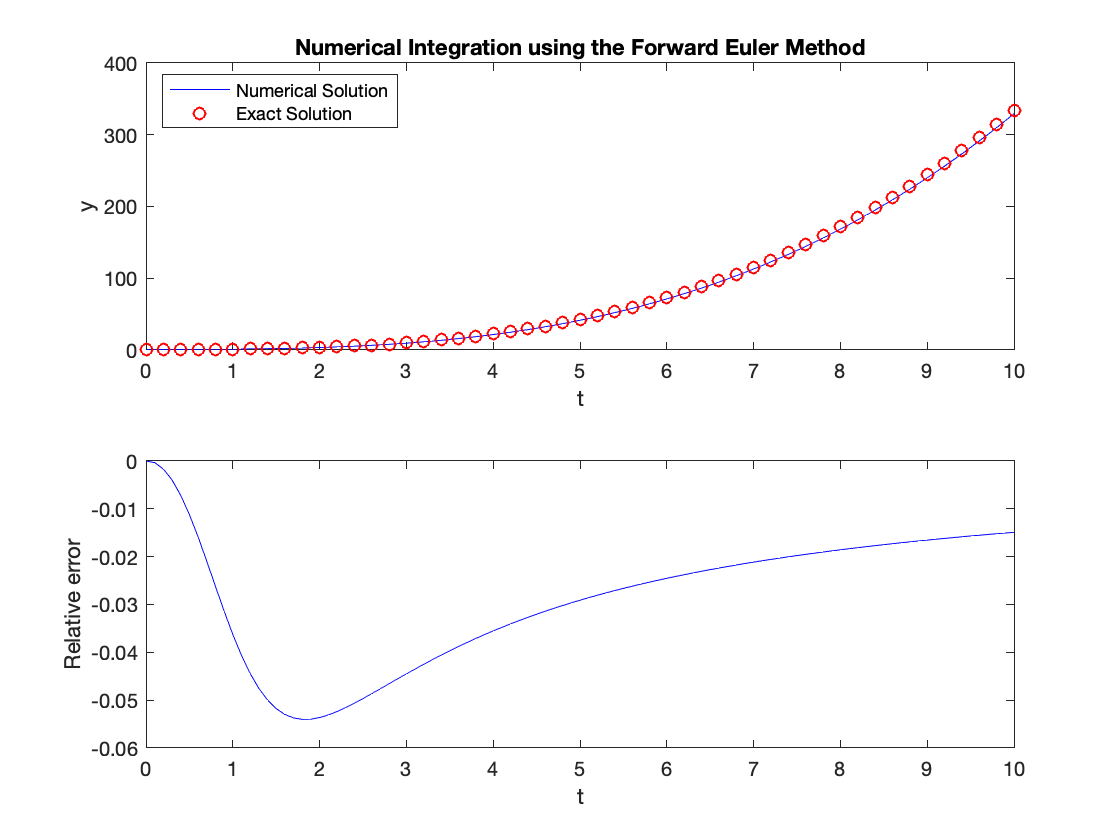

%Set the initial values
t_init = 0.0;
y_init = 1.0;

% Set the final time and the number of time steps to take
t_final = 10.0;
n_steps = 100;

% Use the Forward Euler Method to solve the equation
[t1, y1]   = ForwardEulerMMEES(@TestFcn1, t_init, t_final, y_init, n_steps);

% Calculate the exact solution over the same time interval.
t_exact = t_init : 0.2 : t_final;
y_exact = @(t) (1.0/3.0) * t.^3 + 1.0;

% Plot the numerical and exact solutions as well as the relative error
figure
subplot(2,1,1)
plot(t1, y1, 'b-', t_exact, y_exact(t_exact), 'ro')
xlabel('t')
ylabel('y')
title('Numerical Integration using the Forward Euler Method')
legend('Numerical Solution', 'Exact Solution', 'Location', 'Northwest')

subplot(2,1,2)
plot(t1, (y1 - y_exact(t1))./y_exact(t1), 'b-')
xlabel('t')
ylabel('Relative error')

***Exercise:**** Investigate what happens to the accuracy of the solution as the number of steps is increased and decreased.*

***Exercise:**** Use the Forward Euler method to numerically solve the equation*


$$\frac{d^2y}{dt^2} + 3\frac{dy}{dt} - 2y = \exp(2t), \qquad \frac{dy}{dt}(t=0) = 0, \quad y(t=0) = 1, $$


# The Backward Euler Method

As discussed in Chapter 6, the Backward Euler Method is an implicit method, and so requires us to also solve a non-linear equation in order to find the solution. Here, we solve the same problem as above. 

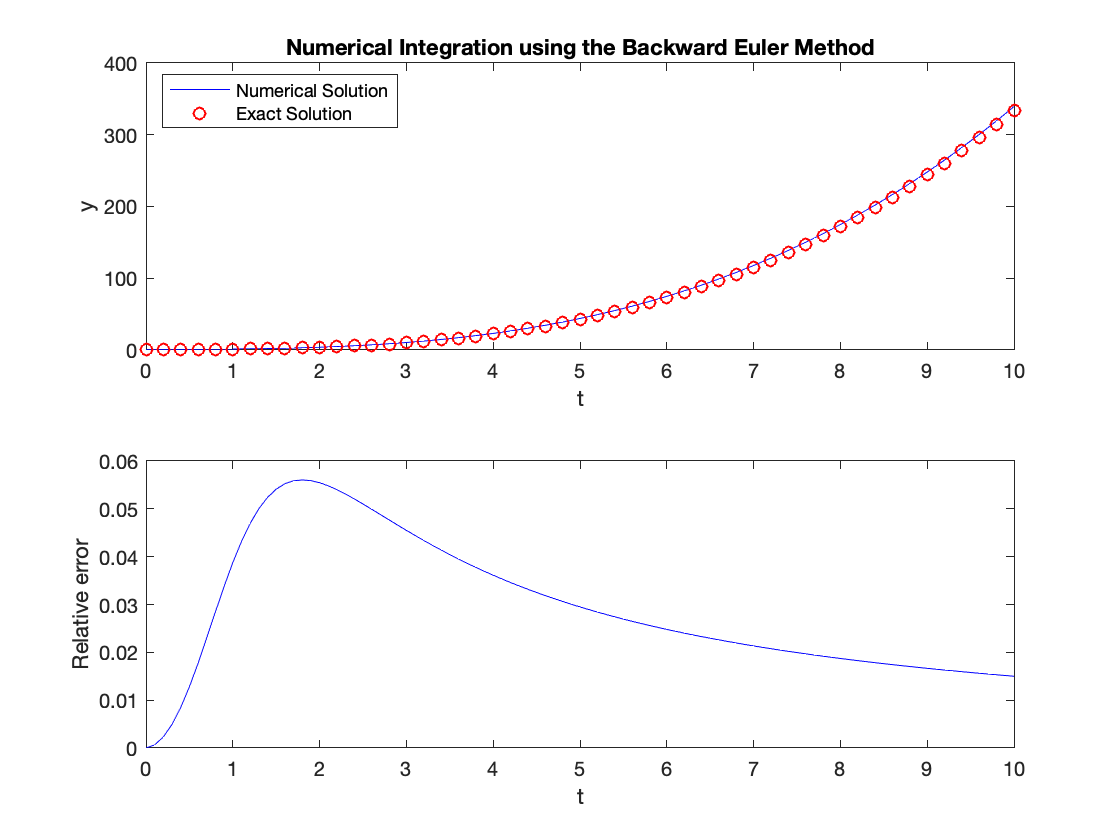

% Set the initial conditions
t_init = 0.0;
y_init = 1.0;

% Set the final time and the number of steps to use
t_final = 10.0;
n_steps = 100;


% Solve the equation using the Backwards Euler Method
[t2, y2]   = BackwardEulerMMEES(@TestFcn1, t_init, t_final, y_init, n_steps);

% Plot the solution and the relative error. 
figure
subplot(2,1,1)
plot(t2, y2, 'b-', t_exact, y_exact(t_exact), 'ro')
xlabel('t')
ylabel('y')
title('Numerical Integration using the Backward Euler Method')
legend('Numerical Solution', 'Exact Solution', 'Location', 'Northwest')

subplot(2,1,2)
plot(t2, (y2 - y_exact(t2))./y_exact(t2), 'b-')
xlabel('t')
ylabel('Relative error')

***Exercise: ****Investigate what happens to the accuracy of the solution as the number of steps is increased and decreased.*

***Exercise:**** Use the Backward Euler method to numerically solve the equation*


$$\frac{d^2y}{dt^2} + 3\frac{dy}{dt} - 2y = \exp(2t), \qquad \frac{dy}{dt}(t=0) = 0, \quad y(t=0) = 1, $$


# The Runge-Kutta Method

The Runge-Kutta method is really a suite of algorithms that all use the same methodology. The 4th order Runge-Kutta algorithm is one of the algorithms of choice as a first algorithm to use when solving ordinary differential equations. In the example below we use a very simple version of the algorithm, but more sophisticated versions that have added refinements to the accuracy and employ techniques such as adaptive step sizing are commonly used; the solvers built in to Matlab include many of these refinements. Books on numerical methods such as *Numerical Recipes* by Press et al. (Cambridge University Press) are a good place to start to learn about these techniques.

Below we will solve the same problem as we used for the Euler methods, but notice that we use far fewer step sizes!

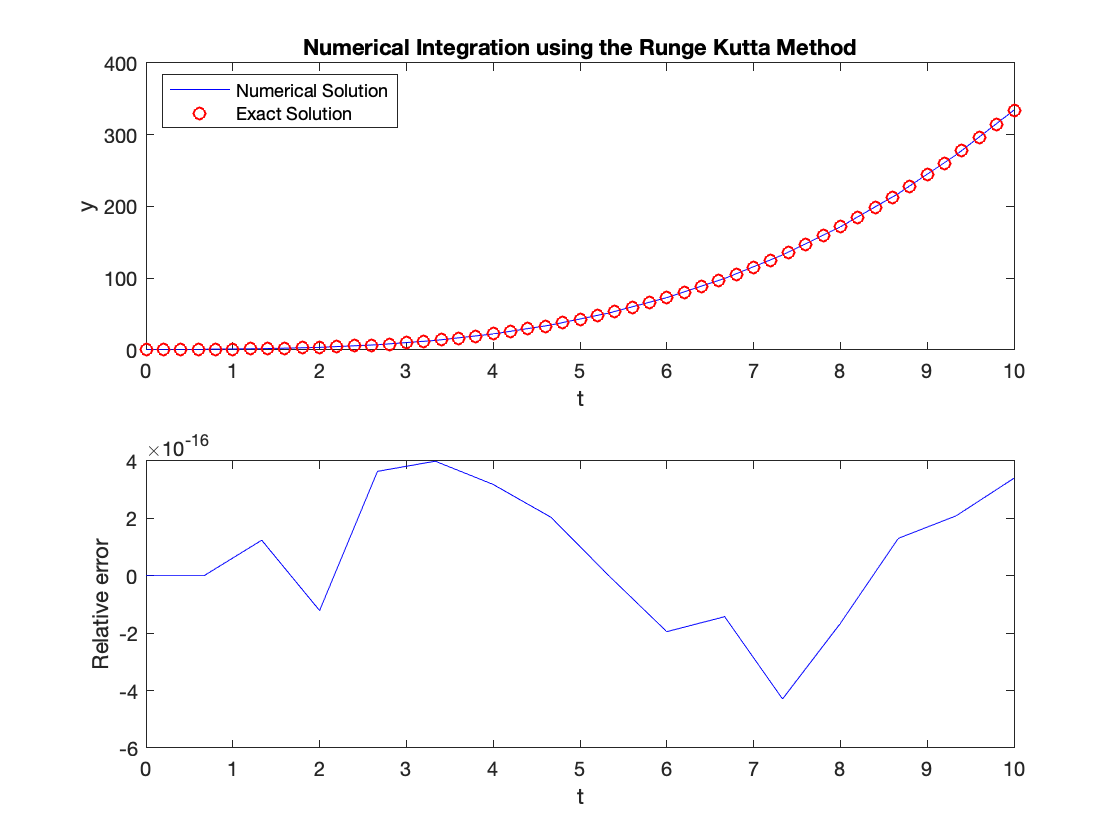

% Set the initial condition
t_init = 0.0;
y_init = 1.0;

% Set the final time and the number of steps.
t_final = 10.0;
n_steps = 15;

% Solve the equations using a 4th order Runge-Kutta routine
[t1rk, y1rk] = RungeKutta4MMEES(@TestFcn1, t_init, t_final, y_init, n_steps);

% Plot the solution and the relative error
figure
subplot(2,1,1)
plot(t1rk, y1rk, 'b-', t_exact, y_exact(t_exact), 'ro')
xlabel('t')
ylabel('y')
title('Numerical Integration using the Runge Kutta Method')
legend('Numerical Solution', 'Exact Solution', 'Location', 'Northwest')

subplot(2,1,2)
plot(t1rk, (y1rk - y_exact(t1rk))./y_exact(t1rk), 'b-')
xlabel('t')
ylabel('Relative error')

Notice that even with a much smaller number of steps, the solution we calculate is far more accurate than the one obtained using either Euler method. This is efficiency and accuracy are among the main reasons why Runge-Kutta algorithms are so popular.

***Exercise: ****Investigate what happens to the accuracy of the solution as the number of steps is increased and decreased.*

***Exercise:**** Use the Backward Euler method to numerically solve the equation*


$$\frac{d^2y}{dt^2} + 3\frac{dy}{dt} - 2y = \exp(2t), \qquad \frac{dy}{dt}(t=0) = 0, \quad y(t=0) = 1, $$


# Boundary Value Problems

We have to take a slightly different approach to solving boundary value problems involving ordinary differential equations. This is because we do not have all the information we need at the initial condition to simply step forward from that point. Two popular methods for solving such problems are the shooting methods and finite difference methods. 

## Shooting Methods

Shooting methods require us to guess the missing initial values and then use a method such as a Runge-Kutta to find the solution at the other boundary. We then use a root-finding method such as Newton's method or the Secant method to find a better approximation to the boundary condition. 

To look at this, we will solve the bounday value problem


$$y(x)\frac{d^2y}{dx^2} + \left(\frac{dy}{dx}\right)^2 = 0, \qquad y(x=0) = 1,\quad y(x=1) = 2$$


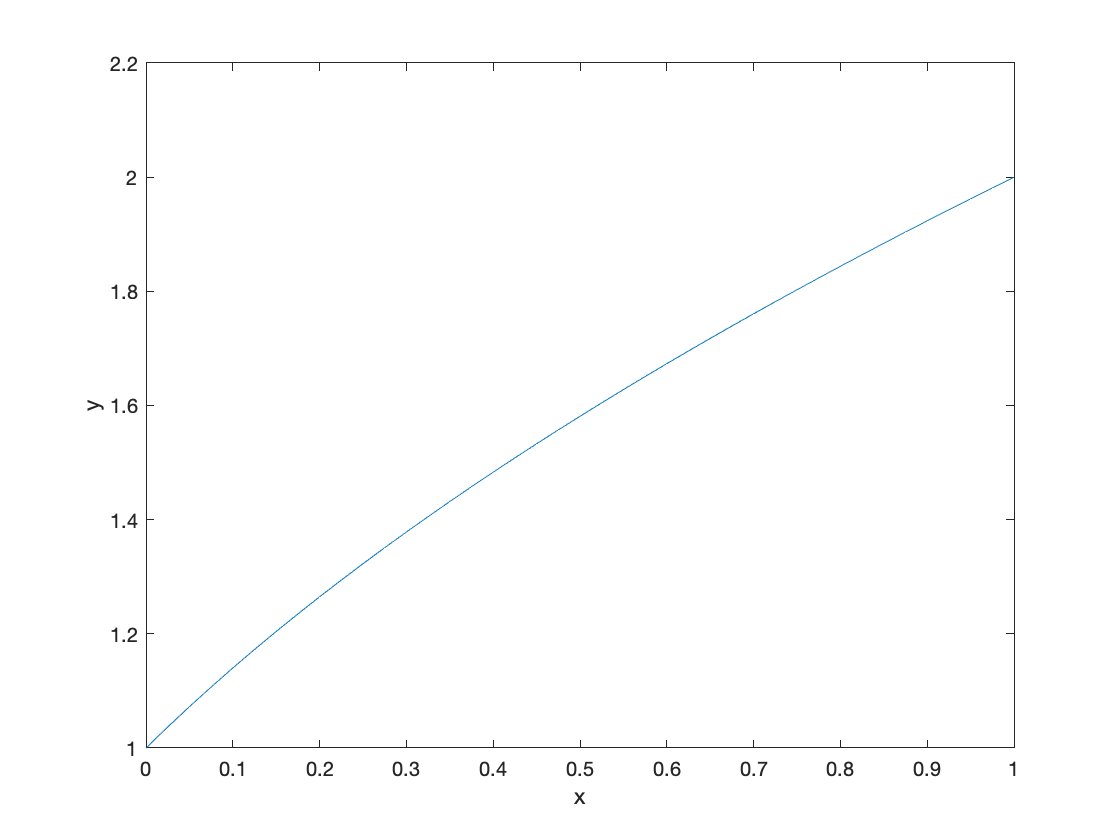

% Set up the left and right boundary conditions
x_left  = 0;
x_right = 1;
y_left  = 1;
y_right = 2;

% Choose two initial guesses for the missing initial condition
guess_1 = 1;
guess_2 = 2;

% Choose a required tolerance for the accuracy of the solution at the right
% boundary
tolerance = 1.0e-5;

[x,y] = ShootingMMEES(@TestFcn2, x_left, x_right, y_left, y_right, guess_1, guess_2, tolerance);

% Plot the solution
figure
plot(x, y(:,1))
xlabel('x')
ylabel('y')

## The Finite Difference Method

We can also solve boundary value problems using a finite difference method. As described in Chapter 6, this results in a large matrix equation that will be slightly different for each differential equation. Rather than create our own code for this, we will make use of Matlab's built-in boundary value solver

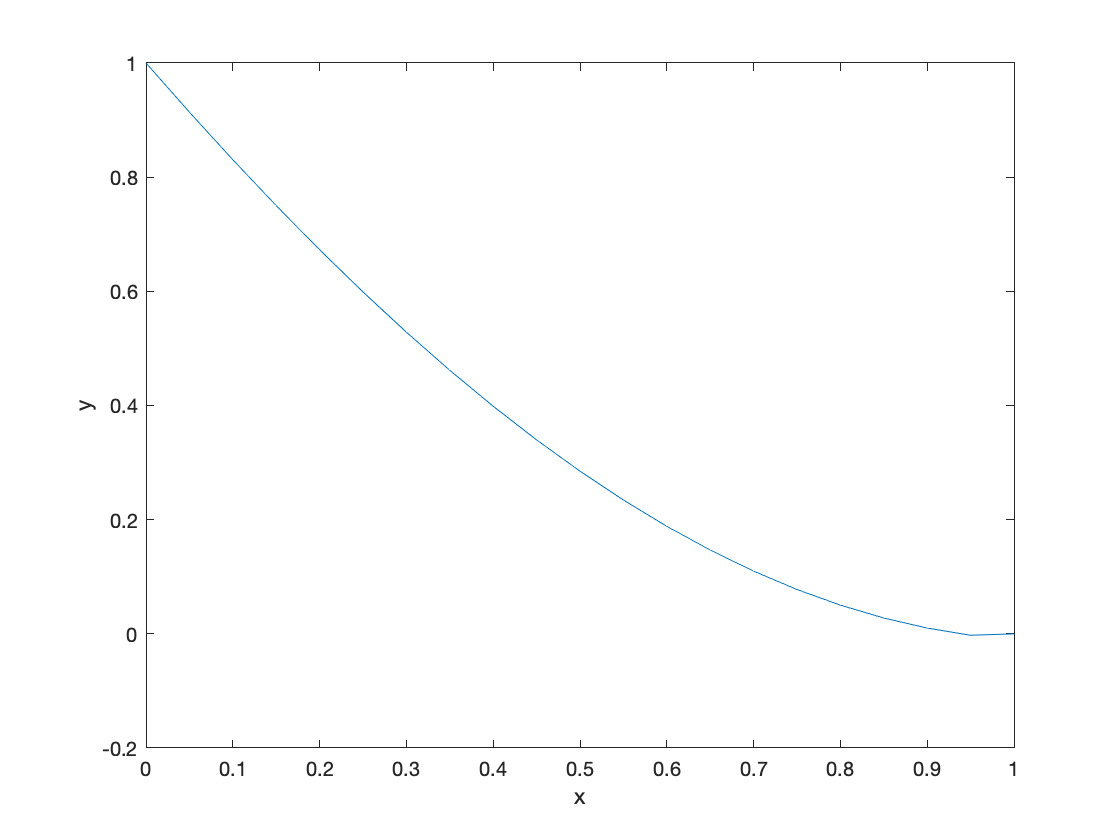

% Set the number of intervals we want to use
n_intervals = 20.0;

% Solve the equation using finite differences
[x, y] = ODEFiniteDiffMMEES(n_intervals);

% Plot the results
figure
plot(x,y)
xlabel('x');
ylabel('y');